clear;

% -ddu/dxx = exp(-cos(x))
% x in [-pi, pi]
% x(-pi) = x(pi)

% parameters
M = pi; 
N = 1024 - 1; 
h = 2*M/(N+1); 
xGrid = -M+h : h : M;

phi = @(x) exp(-cos(x));
f   = @(x) -sin(x);

% first order derivative
col = [0 -1 zeros(1,N-1)]'; 
row = [0  1 zeros(1,N-1)];
SD = toeplitz(col,row);
SD(1,N+1) = -1;
SD(N+1,1) = 1;
SD = SD/(2*h);

% second order derivative
col = [-2 1 zeros(1,N-1)]';
row = [-2 1 zeros(1,N-1)];
TD = toeplitz(col,row);
TD(1,N+1) = 1;
TD(N+1,1) = 1;
TD = TD/(h^2);

A = TD;
% b = phi(xGrid)';
b = f(xGrid)';
x0 = linspace(-pi,pi,N+1)';
tol = 1e-6;
maxit = 100;

[x,res] = iterSolve(A,b,x0,tol,maxit,0)

Max iterations reached.


x =    -0.2472
   -0.2411
   -0.7257
   -0.7196
   -1.1759
   -1.1698
   -1.5824
   -1.5763
   -1.9347
   -1.9286


res = 1.0583

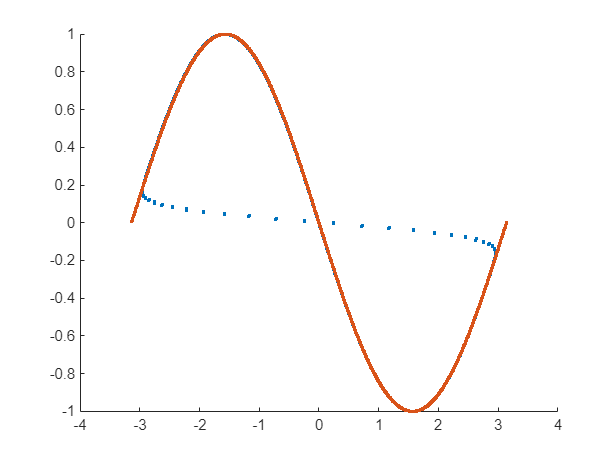

figure();

hold on;
plot(x,b,'.')
plot(xGrid,b,'.')
hold off;

figure();
legend('Location','best');

hold on;
plot(xGrid, TD\phi(xGrid)', '.', ...
    'DisplayName', "TD");
%plot(xGrid, SD*SD*phi(xGrid)', 'x', ...
%    'DisplayName', "SD*SD");
hold off;

figure();
legend('Location','best');

hold on;
plot(xGrid, -cos(xGrid), '.', 'DisplayName', "-cos(x)");
plot(xGrid, TD*f(xGrid)', 'o', 'DisplayName', "TD*f(x)");
plot(xGrid, SD*SD*f(xGrid)', 'x', 'DisplayName', "SD*SD*f(x)");
hold off;